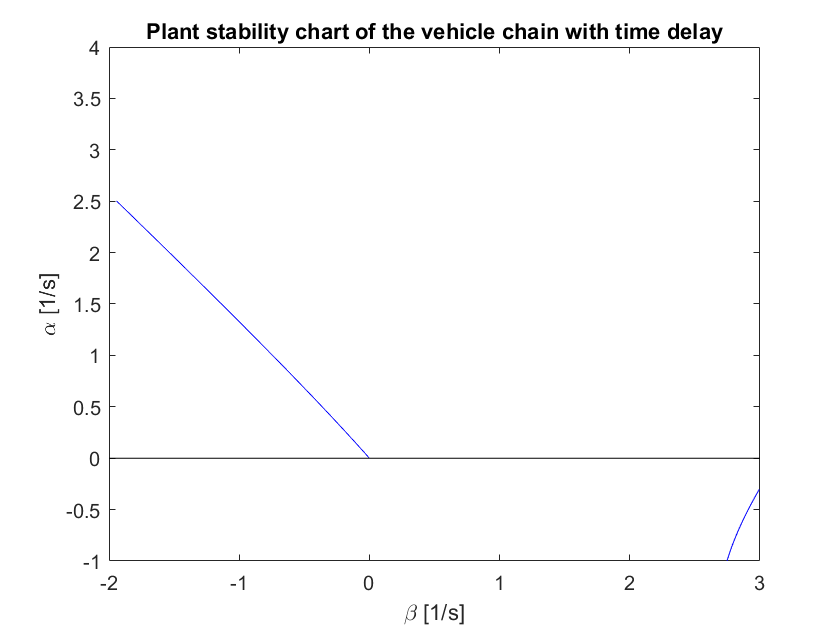

% Stability analysis.
%INPUT: tau, kappa, (A,B,C matrices) or (a_0,a_tau,beta_0,beta_tau C
% matrices in case of time delay system
% HW4_Q1: Human car following model or Car following model with delay.
% Considering OVM.
% Refer HW4

clear all; close all;
syms tau alpha beta kappa om s;

%Inputs
%Comment out tau and kappa to see the expression in symbolic form.
tau = 0.5;
kappa = 0.6;    
a_0 = [0 -1 ; 0 -alpha];
a_tau = [0 0 ; alpha*kappa -beta];
beta_0 = [ 1 ; 0 ];
beta_tau = [ 0 ; beta];
C = [ 0 1 ];
I = eye(2);

%Transfer function and Denominator's determinent
TF = simplify(C*(inv(s*I - a_0 - a_tau*exp(-s*tau)))*(beta_0 + beta_tau*exp(-s*tau)));
Deno = simplify(det(s*I - a_0 - a_tau*exp(-s*tau)));

% Plant stability
Deno_jw  = simplify(rewrite(subs(Deno,s,1i*om),'sin'));
assume([alpha,beta,tau,om,kappa],'real');
real_Deno_jw = real(Deno_jw);
img_Deno_jw = imag(Deno_jw);
assume([alpha,beta,tau,om,kappa],'clear');
plant_stability_plot(alpha,beta,real_Deno_jw,img_Deno_jw);

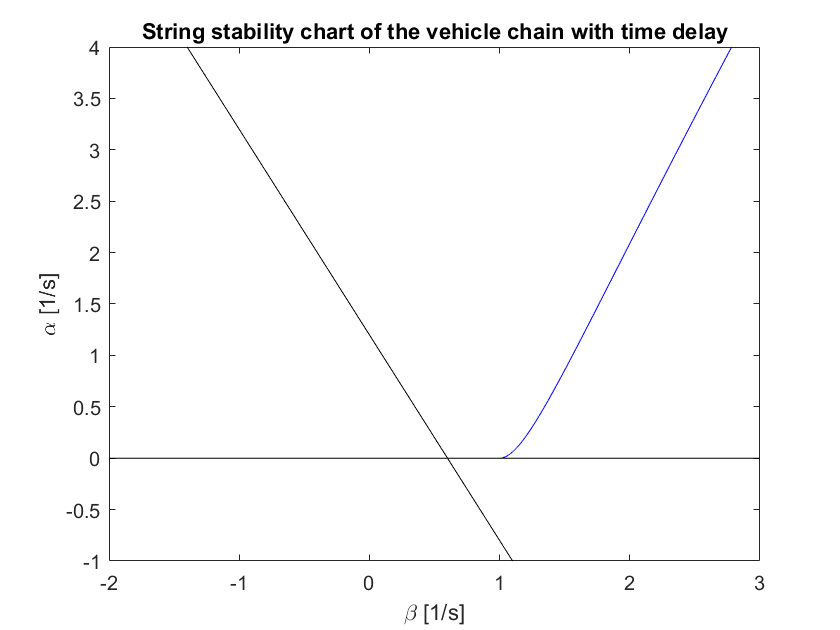


%Sting stability
TF_jw = subs(TF,s,1i*om);
TF_jw  = simplify(rewrite(TF_jw,'sin'));
assume([alpha,beta,tau,om,kappa],'real');
TF_jw_abs = simplify((real(TF_jw)^2+imag(TF_jw)^2)); % calculating square of magnitude of transfer function at j*w
assume([alpha,beta,tau,om,kappa],'clear');
[N,D] = numden(TF_jw_abs);
P = simplify((D-N)/om);
string_stability_plot(P,om,beta,alpha,kappa);

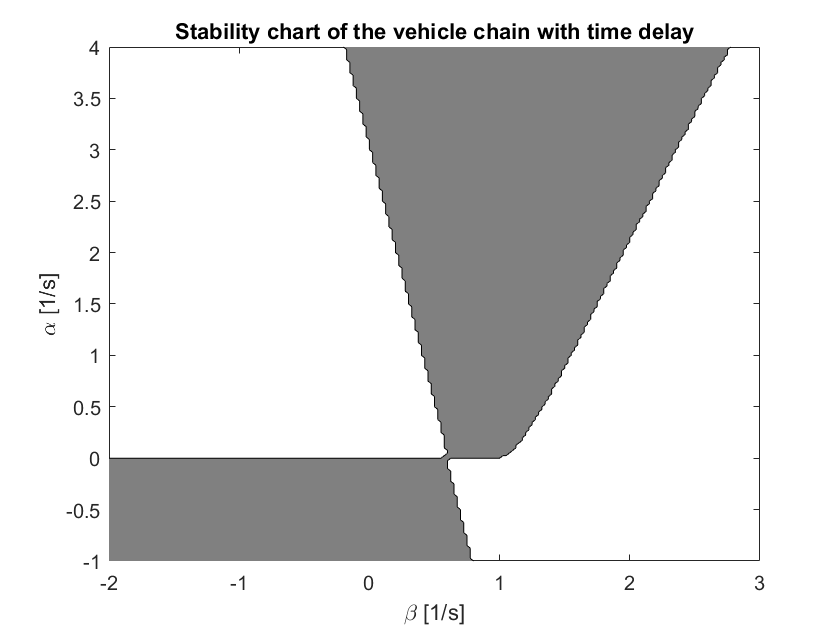

Error using plotedit (line 123)
Functionality not supported with figures created with the uifigure function. For more information, see Graphics Support in App Designer.

Error in uisuspend (line 48)
            'ploteditEnable',        plotedit(fig,'getenabletools'), ...        

Error in 


%Checking which regions are stablity through bruteforce.(Similar to
%Semi-discritization).
%Will have to enter the values of TF manually with dots.
brute_force(tau,kappa);

function plant_stability_plot(alpha,beta,real_Deno_jw,img_Deno_jw)
    
    solu = solve([real_Deno_jw==0,img_Deno_jw==0],[alpha,beta],"MaxDegree",3);
    
    alphamin = -1;
    alphamax = 4;
    betamin = -2;
    betamax = 3;
    
    ommin = 0;
    ommax = 2*pi;
    dom = 0.01;
    om=ommin:dom:ommax;
    
    alpha01=@(beta)0*beta;
    
    figure(1); clf; hold on; box on;
    for ksolu=1:length(solu.beta)
        % evaluate the string stability limit for different values of omega
        betastring=eval(solu.beta(ksolu));      %Evaluating alphas and betas at at the om
        alphastring=eval(solu.alpha(ksolu));
        % remove complex values
        betastring(imag(betastring)~=0)=nan;
        alphastring(imag(alphastring)~=0)=nan;
        % remove possible asymptotes
        betastring(betastring>betamax | betastring<betamin)=nan;
        % plot omega>0 string stability boundaries
        plot(betastring,alphastring,'b');
    end

    plot([betamin,betamax],alpha01([betamin,betamax]),'k');
    axis([betamin betamax alphamin alphamax]);
    xlabel('\beta [1/s]');
    ylabel('\alpha [1/s]');
    title('Plant stability chart of the vehicle chain with time delay');
end




function string_stability_plot(P,om,beta,alpha,kappa)
    
    
    Q = diff(P,om);
    
    solu = solve([P==0,Q==0],[beta,alpha],'MaxDegree',3);
    
    alphamin = -1;
    alphamax = 4;
    betamin = -2;
    betamax = 3;
    
    ommin = 0;
    ommax = 2*pi;
    dom = 0.01;
    om=ommin:dom:ommax;
    
    %For non-oscilating boundaries
    alpha01=@(beta)0*beta;
    alpha02=@(beta)2*(kappa-beta);
    
    figure(1); clf; hold on; box on;
    for ksolu=1:length(solu.beta)
        % evaluate the string stability limit for different values of omega
        betastring=eval(solu.beta(ksolu));
        alphastring=eval(solu.alpha(ksolu));
        % remove complex values
        betastring(imag(betastring)~=0)=nan;
        alphastring(imag(alphastring)~=0)=nan;
        % remove possible asymptotes
        betastring(betastring>betamax | betastring<betamin)=nan;
        % plot omega>0 string stability boundaries
        plot(betastring,alphastring,'b');
    end
    
    plot([betamin,betamax],alpha01([betamin,betamax]),'k');
    plot([betamin,betamax],alpha02([betamin,betamax]),'k');
    axis([betamin betamax alphamin alphamax]);
    xlabel('\beta [1/s]');
    ylabel('\alpha [1/s]');
    title('String stability chart of the vehicle chain with time delay');
    

end




function brute_force(tau,kappa)
    
    % range of parameters
    betamin=-2;    
    betamax=3;     
    alphamin=-1;	
    alphamax=4;     
    step=200;

    
    % range of frequencies
    ommin=0;
    ommax=2*pi;
    dom=0.05;
        
    % vectors of parameter and frequency values
    alpha_v=linspace(alphamin,alphamax,step+1);
    beta_v=linspace(betamin,betamax,step+1);
    om_v=ommin:dom:ommax;
    
    % matrix of parameter, frequency and transfer function values
    [beta,alpha,om] = meshgrid(beta_v,alpha_v,om_v);
    T = (alpha*kappa + beta.*om.*1i)./(alpha*kappa + beta.*om.*1i - om.^2.*cos(om.*tau) - om.^2.*sin(om.*tau).*1i + alpha.*om.*cos(om.*tau).*1i - alpha.*om.*sin(om.*tau));
    M=abs(T);


    % same with for loops
    stab = zeros(length(alpha_v),length(beta_v));
    for kb=1:length(beta_v)
        for ka=1:length(alpha_v)
        stab(ka,kb)=all(squeeze(M(ka,kb,2:end))<1);
        end
    end
    
    %% Plot stability chart
    figure(1); clf; hold on; box on;
    contourf(beta(:,:,1),alpha(:,:,1),stab,[1 1],'k')
    colormap gray
    xlabel('\beta [1/s]')
    ylabel('\alpha [1/s]')
    axis([betamin betamax alphamin alphamax]);
    title('Stability chart of the vehicle chain with time delay');
    
    %% Plot frequency response
    figure(1); [beta0,alpha0]=ginput(1);    % (beta,alpha) by clicking on stability chart
    % beta0=0.4; alpha0=0.2;                % or given (beta,alpha)
    
    % get closest parameter values to the selected ones
    beta0=interp1(beta_v,beta_v,beta0,'nearest');
    alpha0=interp1(alpha_v,alpha_v,alpha0,'nearest');
    % get corresponding frequency response
    M_v=squeeze(M(alpha_v==alpha0,beta_v==beta0,:));
    
    figure(2); clf; hold on; box on;
    title(['\beta=',num2str(beta0),'   \alpha=',num2str(alpha0)]);
    plot(om_v,M_v);
    plot([ommin ommax],[1 1],'k--');
    xlabel('\omega [rad/s]');
    ylabel('|T(j\omega)|');
    xlim([ommin ommax]);
    title('Frequency response of the vehicle chain with time delay');
    
end


